# Folder Selector

## Create the widget

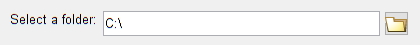

f = figure(...
    'Toolbar','none',...
    'MenuBar','none',...
    'NumberTitle','off',...
    'Units','pixels',...
    'Position',[100 100 420 45]);
movegui(f,[100 -100])

w = uiw.widget.FolderSelector(...
    'Parent', f, ...
    'Value', 'C:\', ...
    'Callback',@(h,e)disp(e),...
    'Label','Select a folder:',...
    'LabelLocation','left',...
    'LabelWidth',90,...
    'Units', 'pixels', ...
    'Position', [10 10 400 25]);

## Set a different value to a path that does not exist

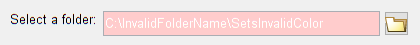

% The color should toggle
w.Value = 'C:\InvalidFolderName\SetsInvalidColor';

## Now, set a valid value

% The color should toggle back
w.Value = 'C:\';